## Name: Maria Eva Vazquez 

## Date: 10/20/2026

## PID: 6296923

## Quiz 4 : Numerical Integration

**General Instructions:** Complete each question to the best of your abilities.  Include comments in your code to explain your thought process while answering.

**Submission Instructions:** Quiz files should be titled Quiz_X_FirstNameLastName, Ex: Quiz_4_AsadMirza. To convert the MLX file into a PDF go to the Export icon under Live Editor and select "Export to PDF".

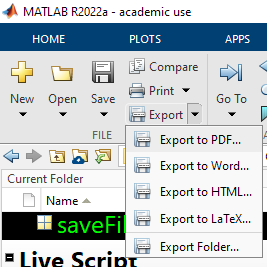

Any scratch paper used should have your name, date, and PID on it and be submitted to me when you finish your quiz.

Question 1 (20%) 

a) (10%) Solve the following ordinary differential equation using Backward Euler’s Method.

$\frac{\textrm{dy}}{\textrm{dt}}=2\,-9\,t^2$ , y(0) = 1

from t=0 to t=2 using a step size of h=0.1

clear; clc; close all;

% % Step 1
h =  0.1;
t = 0:h:2;
y0 = 1;
y(1) = y0;%IC

% Set up function 
f = @(t,y) 2 - 9*t^2;


% % Step 2
s_Back = zeros(size(t));   % >> y_n
s_Back(1) = y0;  
for ii = 1:length(t)-1
    g = @(Y) s_Back(ii) + h * f(t(ii+1), Y) - Y; 
    % Basically:  y_n+1 = y_n + h* f(t_n+1 , y_n+1)
    %    where                       ^t(ii+1) is t_n+1
    s_Back(ii+1) = fzero(g, s_Back(ii));% Solve implicit problem
end


b) (5%) Plot against the real solution of:


$$y=2t-3t^3 +1$$


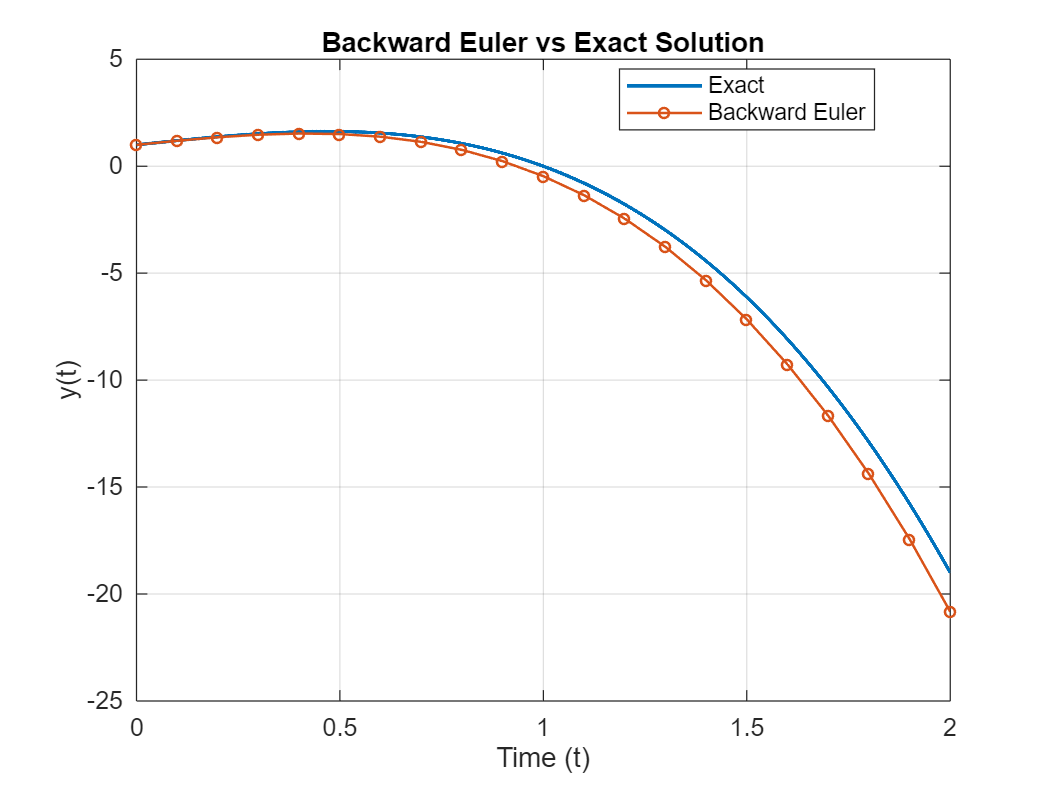

% % Step 3 
% Exact
y_exact=@(t) 2.*t-3.*t.^3+1;

% % Step 4
figure;
tt = linspace(min(t), max(t), 10000);  % smooth time vector for exact solution
plot(tt, y_exact(tt), 'LineWidth', 1.5);   % exact solution
hold on;
plot(t, s_Back, '-o', 'MarkerSize', 4, 'LineWidth', 1);  % Backward Euler result
hold off;
xlabel('Time (t)');
ylabel('y(t)');
legend('Exact', 'Backward Euler', 'Location', 'best');
title('Backward Euler vs Exact Solution');
grid on;

c) (5%) Show the absolute error of the above approximation at y(1).

% % Step 5
t_eval = 1;                                 % time to evaluate error
idx = find(abs(t - t_eval) < 1e-12, 1);      % index closest to t = 1
err_BE = abs(s_Back(idx) - y_exact(t_eval)); % absolute error
fprintf('Backward Euler absolute error at t = %.2f: %.6e\n', t_eval, err_BE);

Backward Euler absolute error at t = 1.00: 4.650000e-01


Question 2 (40%) 

For the function:


$$\frac{\textrm{dy}}{\textrm{dx}}=\frac{y}{4}-\frac{y^2 }{20},\;y\left(0\right)=1$$


The real integral solution is:


$$y=\frac{5e^{\frac{x}{4}} }{e^{\frac{x}{4}} +4}$$


Do the following with a step size of $h=2$

a) (20%) Solve using the Forward Euler Method and plot it and the real solution from x = 0 to 10.

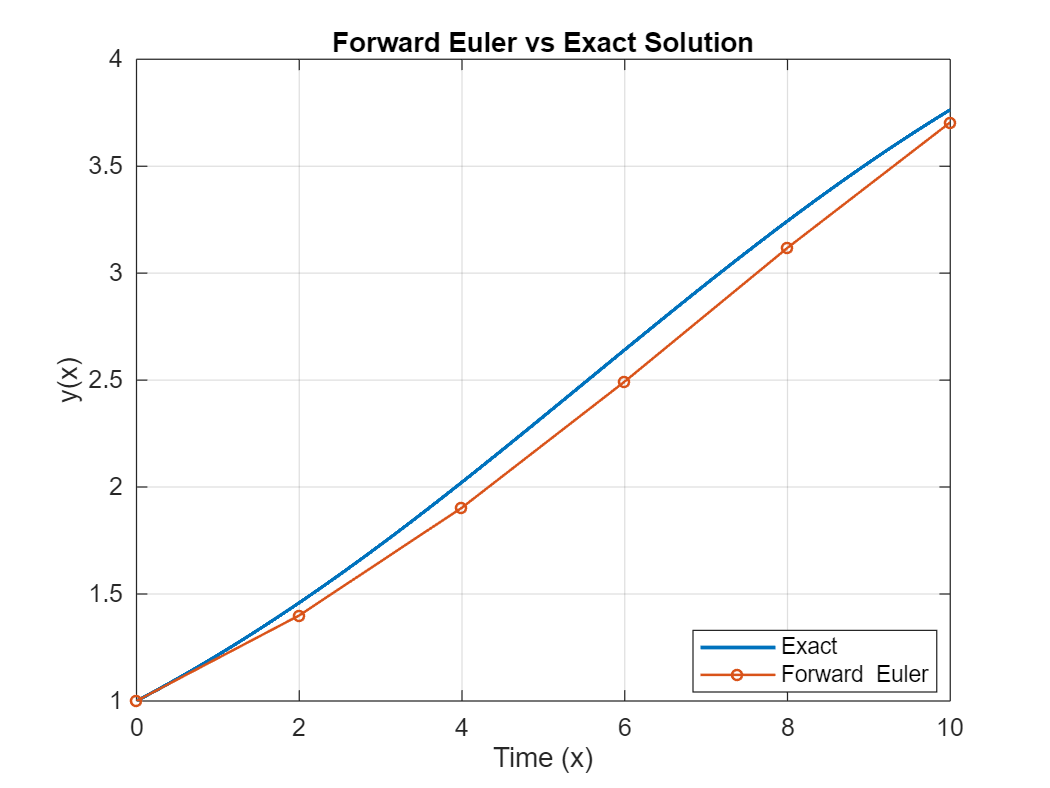

clear,clc,close all

% % Step 1
y0 = 1;  
h = 2;% Step size
x = 0:h:10; % t_n

% Define the function
f = @(t,y) y/4 - y.^2/20;

% % Step 2
t = zeros(1,length(x)); % >> y_n
t(1) = y0;
for ii = 1:length(x)-1
    t(ii+1) = t(ii) + h * f(x(ii),t(ii));
    % Basically:  y_n+1 = y_n + h * f(t_n, y_n)
    %    where                       ^x(ii) is t_n
end

% % Step 3
% Exact solution
t_real = 5 ./ (1 + 4*exp(-x/4));

% % Step 4
figure;
tt = linspace(min(x), max(x), 10000); % smooth for exact solution
plot(tt, 5 ./ (1 + 4*exp(-tt/4)), 'LineWidth', 1.5); % exact
hold on;
plot(x, t, '-o', 'MarkerSize', 4, 'LineWidth', 1); % fowards
hold off;
xlabel('Time (x)');
ylabel('y(x)');
legend('Exact', 'Forward  Euler', 'Location', 'best');
title('Forward Euler vs Exact Solution');
grid on;

b) (20%) Solve using the Central Euler Method and plot it and the real solution from x = 0 to 10.

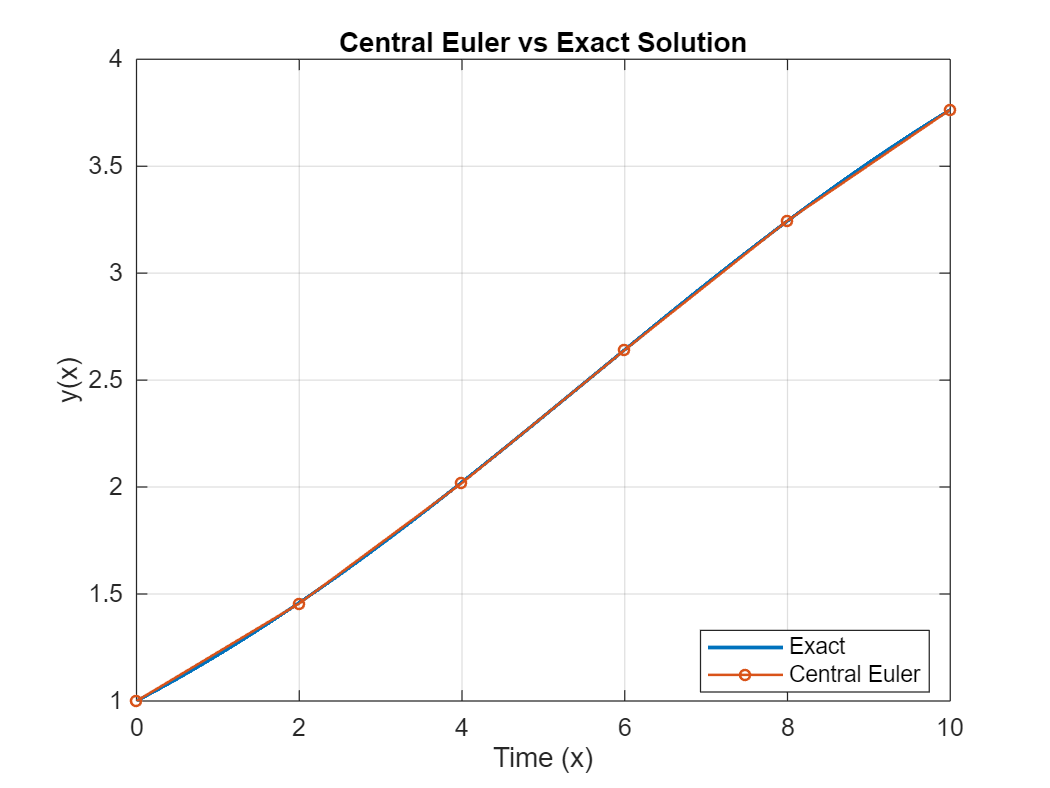

% % Step 5
t_C = zeros(1,length(x)); % >> y_n
t_C(1) = y0;
for ii = 1:length(x)-1
    % First, value at the midpoint
    t_mid = t_C(ii) + (h/2) * f(x(ii),t_C(ii));
    x_mid = x(ii) + h/2;
    % Basically:  y_n+1/2 = y_n + h/2 * f(x_n, y_n)
    %    where                         ^x(ii) >> x_n

    % Second, the midpoint value to calculate the next
    t_C(ii+1) = t_C(ii) + h * f(x_mid,t_mid);
    % Basically:  y_n+1 = y_n + h * f(x_n+1/2, y_n+1/2)
    %    where                       ^x_mid >> x_n+1/2
end


% % Step 6
figure;
tt = linspace(min(x), max(x), 10000); % smooth for exact solution
plot(tt, 5 ./ (1 + 4*exp(-tt/4)), 'LineWidth', 1.5); % exact
hold on;
plot(x, t_C, '-o', 'MarkerSize', 4, 'LineWidth', 1); % central
hold off;
xlabel('Time (x)');
ylabel('y(x)');
legend('Exact', 'Central Euler', 'Location', 'best');
title('Central Euler vs Exact Solution');
grid on;

Question 3 (40%) 

A newly planted forest plant biomass will be constantly changing between different stages. Most will reside as living trees, but eventually they die from age and other events. The dead trees will eventually decay and fall and be converted into humus. 

A typical yearly biological model is:


$$x^{\prime } =-3x\left(t\right)+\;6z\left(t\right)$$



$$y^{\prime } =-2y\left(t\right)+3x\left(t\right)$$



$$z^{\prime } =-6z\left(t\right)+2y\left(t\right)$$


Where $x$ is the amount living trees biomass and $y$ is the amount of dead trees biomass and $z$ is the humus biomass.

a) (30%) If we have no dead trees or humus at the start planting, plot the coupled system with 1500 initially planted trees during 6 years.

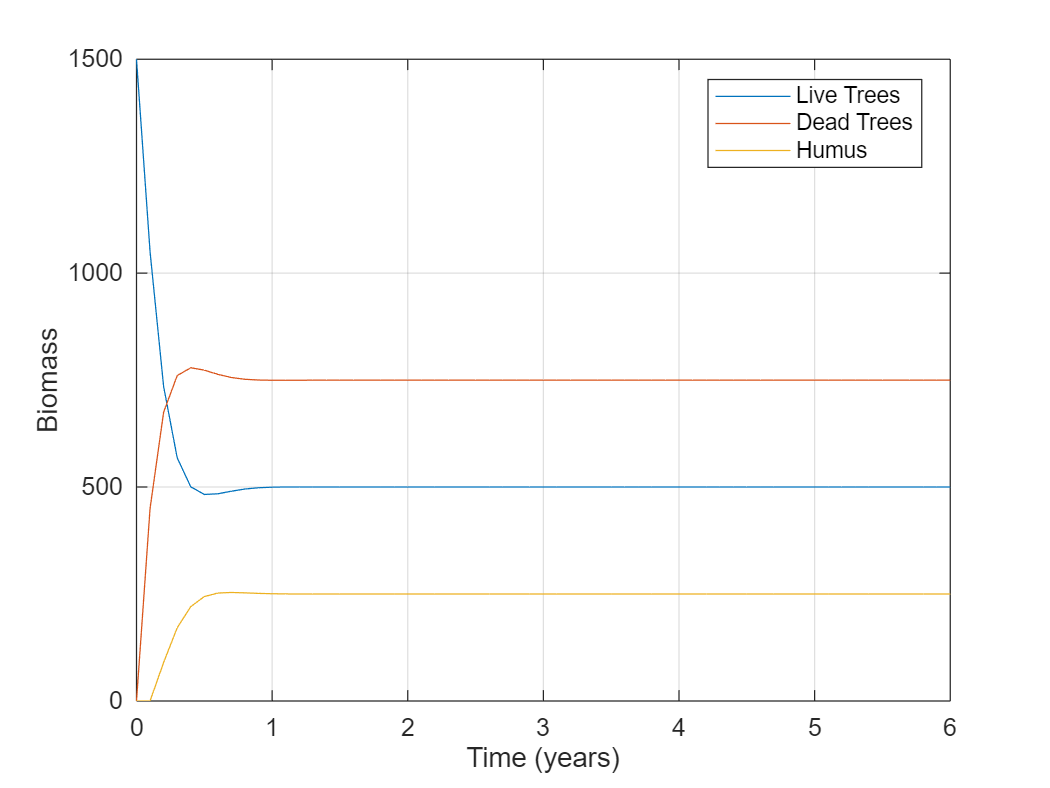

% % Step 1
h = 0.1; % Time step, 0.1 years
t = 0:h:6; % 6-year period
P0trees = 1500; % Initial planted trees
P0dead = 0; % Initial dead trees 
P0humus = 0; % Initial hummus



% % Step 2
% Live Trees
Ptrees = zeros(1, length(t)); % Pre-allo
Ptrees(1) = P0trees; % Set initial 
% Dead Trees
Pdead = zeros(1, length(t)); % Pre-allo
Pdead(1) = P0dead;% Set initial
% Hummus
Phummus = zeros(1, length(t)); % Pre-allo
Phummus(1) = P0humus; % Set initial



% % Step 3
dPtress = @(x1, x2, x3) -3*x1 + 6*x3; % Rate of change for live trees
%                  x' = -3x(t) + 6z(t)
dPdead = @(x1, x2, x3) 3*x1 - 2*x2;   % Rate of change for dead trees
%                  y' = -2y(t) + 3x(t)
dPhummus = @(x1, x2, x3) 2*x2 - 6*x3; % Rate of change for humus
%                  z' = -6z(t) + 2y(t)

% x1 = Ptrees
% x2 = Pdead
% x3 = Phummus

% % Step 4
for k = 1:length(t)-1
    % P_k+1 = P_k + h*f(P_k)
    %        AKA. New value = current value + time step × current rate of change.
    % In this case:
    %       |Ptrees(K) |
    % P_k = |Pdead(k)  |
    %       |Phummus(k)|
    % Live Trees
    Ptrees(k+1) = Ptrees(k) + h*dPtress(Ptrees(k), Pdead(k), Phummus(k));
    % Dead Trees
    Pdead(k+1) = Pdead(k) + h*dPdead(Ptrees(k), Pdead(k), Phummus(k));
    % Hummus
    Phummus(k+1) = Phummus(k) + h*dPhummus(Ptrees(k), Pdead(k), Phummus(k));
end



% % Step 5
figure
plot(t, Ptrees)
hold on
plot(t, Pdead)
plot(t, Phummus)
hold off
xlabel('Time (years)')
ylabel('Biomass')
legend('Living Trees', 'Dead Trees', 'Hummus', 'Location', 'best')
grid on

b) (10%) At the end of the 6 years what is the amount of biomass for live trees,dead trees, and humus?

fprintf('The amount of living biomass is %3.2f\n', Ptrees(end))
fprintf('The amount of dead biomass is %3.2f\n', Pdead(end))
fprintf('The amount of humus biomass is %3.2f\n', Phummus(end))